# Stability analysis, discrete control systems 

This livescript file reviews the main concepts of stability of discrete control systems using several popular methods such as analysing the pole-zero configuration of the closed loop control system, the root locus method, Nyquist criterion  and more. In particular in illustrates how MATLAB tools from within the  control toolbox can be used to support this analysis and remove the need for tedious paper and pen based number crunching. Specifically, this file summarises the engineering and analytical background alongside some simple MATLAB code snippets that can be used for the equivalent analysis.

### Resources and similar files and the toolbox

**Control Engineering: MATLAB Exercises, by L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019**   

[Modelling, Dynamics and Control - Section six: Behaviour characterisation for any order system ](https://sites.google.com/sheffield.ac.uk/controleducation/chaptermodelling/sectionmodellingbehaviours)

[https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

[https://sites.google.com/sheffield.ac.uk/controleducation/chapterdiscrete](https://sites.google.com/sheffield.ac.uk/controleducation/chapterdiscrete)

**Chapter related to stability**: Ch. 2, Section 6.4. 

Stability of continuous systems is discussed in file ***Stability_Cont.mlx***

Design procedures ensuring stability and also prescribed quality specifications for discrete systems using pole cancellation technique is discussed in the file 

***discrete_models_and_discrete_PID_controller_design.***

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by Ruth Bars and Gyula Max, Budapest University of Technology and Economics

 

with small input from J.A. Rossiter, University of Sheffield

## Table of contents

- The concept of stability

- Mathematical formulation of stability of a closed loop sampled control system

- The zero order hold introduces an extra delay into the system

- Analysing the pole-zero map

- Root locus method

- Stability analysis based on the Bode diagram

## 1.The concept of stability and general background

Control systems are based on negative feedback. In a simple control loop the reference signal is compared to the measured output signal. The error signal provides the input of the controller. The output of the controller is the input of the system to be controlled (see the figure below). 

In a sampled system the signals are sampled with an appropriately chosen sampling time. The operations are executed in every sampling point. As the process is continuous, it requires continuous input signal. The discrete output of the controller is held between two sampling points generally with a zero order hold element which keeps the control signal through the sampling period. The sampled signals are described by their z-transforms, and the process and the controller are given by their pulse transfer functions (see files ***discrete_models_and_usage.mlx*** and ***discretisation_and_bode.mlx***).

It should be ensured that the output of the system tracks the reference signal after deceasing of the transients.

     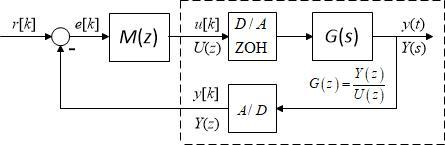

Quality specifications are set for the control system. For example:

- As the signal flow in the system needs time, achieving a steady state must be ensured. Because of the delays and amplifications in the individual elements the settling of the output signal is not always ensured. It is noted that sampling introduces an extra delay in the system. 

- No steady or increasing oscillations are allowed. This means that the control system should be stable. One formulation of stability is that for convergent reference signal the output signal should be also convergent.

- Tracking should be ensured with a prescribed accuracy if the steady state has been already reached. There are prescriptions also for the transient process as settling time, overshoot, etc. Quality specifications can be formulated in the time domain and also in the frequency domain.

- One of the most important properties of linear control systems is stability. A general formulation of stability says that a system is stable if removing it from a stable state the system returns to the original state providing no external input is applied. Another formulation of stability is called BIBO stability, i.e. bounded inputs result in bounded outputs in case of stable systems. Or as mentioned above for convergent reference signal the output signal should be also convergent.

- Stability of a control system has to be distinguished from the stability of the process itself. Either the process itself is stable or unstable, using a proper control system the closed loop system may become stable.

There are several methods to check the stability of a control system. Some methods just give evaluation whether the system is stable or not, while other methods provide measures how far is the system from the boundary of stability. These measures can be used for controller design ensuring stability and also the prescribed quality specifications (see the referred files above).

## 2. Mathematical formulation of stability of a closed loop sampled control system

Consider the closed-loop system given in the figure below. The open-loop pulse transfer function is *L(z)=M(z)G(z)*, and a unity feedback is applied around it.

                 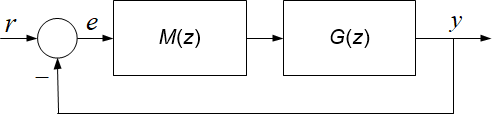

The overall pulse transfer function of the closed-loop system between the z-transforms of the output *y(z)* and the reference signal *r(z)* is:

                   
$$T\left(z\right)=\frac{y\left(z\right)}{r\left(z\right)}=\frac{M\left(z\right)G\left(z\right)}{1+M\left(z\right)G\left(z\right)}=\frac{L\left(z\right)}{1+L\left(z\right)}$$
            

The file ***closedloop_transferfunctions_with_feedback.mlx  ***shows in detail how to form closed loop transfer functions in MATLAB so that is not repeated here.

It is well known that all the components of the transient response will decay once the roots of the characteristic equation $1+L\left(z\right)=0\;$ are  located inside the unit circle in the complex plane. The characteristic equation contains the denominator polynomial of the closed-loop pulse transfer function above. Consequently, roots of the characteristic equation are identical to the poles of the closed-loop system. 

## 3. The zero order hold introduces an extra delay into the system

The figures below show the output of the zero order hold (ZOH) element for a Dirac delta input.

                               

                            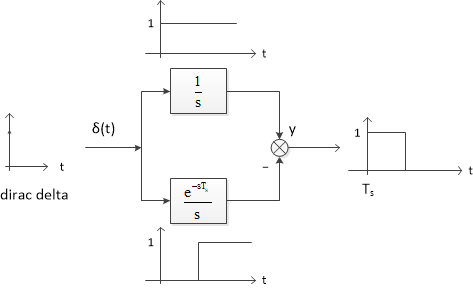

The transfer function of the ZOH element is:


$$W_{\textrm{ZOH}} \left(s\right)=\frac{1-e^{-sT_s } }{s}\approx \frac{1-\left(1-sT_s +\frac{{T_s^2 \;s}^2 }{2}-\cdots \right)}{s}=T_s \left(1-\frac{sT_s }{2}+\cdots \right)\approx T_s {\;e}^{-s\;\;\frac{T_s }{2}}$$
 

This means that with sampling and applying the ZOH element an extra dead time is introduced whose value is approximately the half of the sampling time.

Therefore for sampled systems there are no structurally stable systems.

#### 3.1  Example

Let us analyse the stability of a control system where the process is a pure integrator, *G*(s)=1/s,  and the controller is a proportional element with gain *M*=*K*. In continuous case the control system is structurally stable, that is, it is stable for any *K* value. In discrete case stability depends on the sampling time.

The pulse transfer function of the integrator is


$$G\left(z\right)=\frac{T_s }{z-1}$$


and the pulse transfer function of the closed loop system is


$$T\left(z\right)=\frac{K\frac{T_s }{z-1}}{1+K\frac{T_s }{z-1}}=\frac{KT_s }{z-\left(1-KT_s \right)}$$


The system is stable if the pole is inside the unit circle, i.e.

$\left|1-KT_s \right|<1,\;\;\;\;i\ldotp e\ldotp \;\;\;\;0<KT_s$< 2.

For the continuous system let us choose K=1, 2 ,3 ,4 , 5.

For the discrete system let us choose K=1 and $T_s =0\ldotp 5,1\ldotp 9,2\ldotp 5\ldotp$

%continuous case
disp('EXAMPLE 3.1')

EXAMPLE 3.1


disp('Continuous case')

Continuous case


disp('The transfer function of the continuous closed loop system for different K')

The transfer function of the continuous closed loop system for different K


s=tf('s');
P=1/s;
t=0:0.1:5;
figure(1)
for K=1:5
    T=K/(s+K)
    y=step(T,t);
    plot(t,y),grid
    hold on
end

T =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties
T =
 
    2
  -----
  s + 2
 
Continuous-time transfer function.


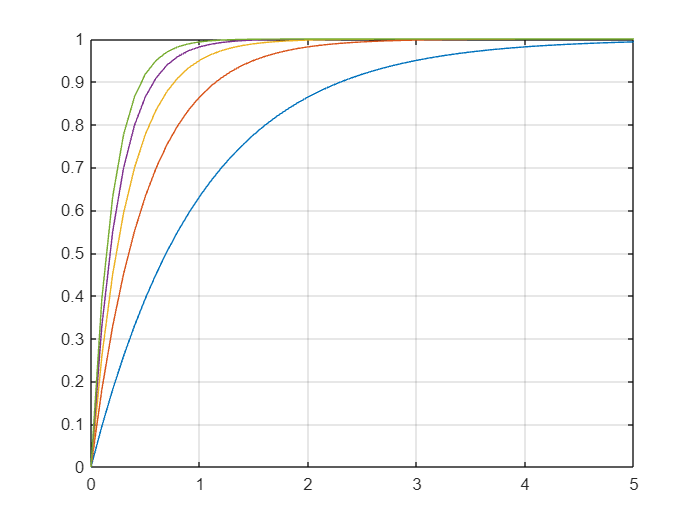

hold off

It is seen that the control system is stable for all the gains. The closed loop system is a first order lag element.

%discrete case
disp('Discrete case')

Discrete case


K=1;

K = 1

Ts=0.5;
z=tf('z',Ts);
Tz1=K*Ts/(z-(1-K*Ts))

Tz1 =
 
    0.5
  -------
  z - 0.5
 
Sample time: 0.5 seconds
Discrete-time transfer function.
Model Properties


Ts=1.9;
z=tf('z',Ts);
Tz2=K*Ts/(z-(1-K*Ts))

Tz2 =
 
    1.9
  -------
  z + 0.9
 
Sample time: 1.9 seconds
Discrete-time transfer function.
Model Properties


Ts=2.1;
z=tf('z',Ts);
Tz3=K*Ts/(z-(1-K*Ts))

Tz3 =
 
    2.1
  -------
  z + 1.1
 
Sample time: 2.1 seconds
Discrete-time transfer function.
Model Properties


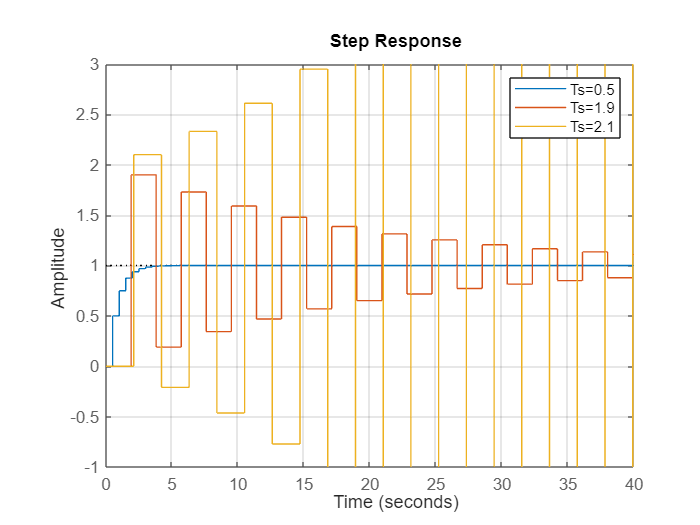

step(Tz1,Tz2,Tz3,40),grid
ylim([-1,3])
legend('Ts=0.5','Ts=1.9','Ts=2.1')

It is seen that the discrete system becomes unstable when $KT_s >2$.

**Remark**: The process is continuous and sampled using zero order hold at its input. The step responses show the behaviour only in the sampling points. To see also the intersampling performance it is adviced to use SIMULINK.

## 4. Analysing the pole-zero map

Let us remind ourselves that the z operator is defined as


$$z=e^{sT_s }$$


The transfer functions and the pulse transfer functions of an integrator, a first order and a second order lag element supposing zero order hold are given as: 

In case of lag elements the number of the discrete poles is equal to the number of the continuous poles, but extra zeros do appear in the pulse transfer function whose number is less by one than the number of the continuous poles.

- The imaginary axis of the s plane is mapped into the unit circle in the z plane. 

- The continuous system is stable if its poles are on the left side of the complex plane. 

- The discrete system is stable if its poles are inside the unit circle.

Let us consider a second order oscillating element with damping factor $\xi =0\ldotp 4$. Its transfer function is $\frac{A}{1+2\xi \textrm{sT}+{T^2 s}^2 }$. The poles in the s domain are


$$s_{1,2} =-\frac{\xi }{T}\pm i\frac{1}{T}\sqrt{1-\xi^2 }=-\sigma \pm i\frac{\sigma }{\xi }\sqrt{1-\xi^2 }$$


With constant damping factor and changing time constant *T, *mapping this line in the z domain, we get a "heart shape" curve. 

If the closed loop transfer function can be approximated with a second order oscillating element and the discrete poles lie inside the "heart curve" then the closed loop is stable and its dynamic performance can be charaterised by the given damping factor.

The code below demonstrates the how the location of under-damped poles of the discrete control system depend upon the sample rate.

% Mapping of the imaginary axis and the location of the poles
% of a second order oscillating element from the s domain into the z domain 
disp('Section 4 below')

Section 4 below


clear
clf
om=0:0.1:100;
Ts=1;
z1=exp(-i*om*Ts);
plot(real(z1),imag(z1)),grid
hold on
disp('The imaginary axis of the s domain is mapped ')

The imaginary axis of the s domain is mapped 


disp('into the unit circle in the z domain')

into the unit circle in the z domain


szigma=0:0.01:6;
kszi=0.4;
z=exp(Ts*(-szigma+i*sqrt(1-kszi*kszi)*szigma/kszi));
plot([real(z),fliplr(real(z))],[imag(z),fliplr(-imag(z))])
legend('Unit circle','Pole dependence on sample rate ')
disp('The constant damping factor line is mapped') 

The constant damping factor line is mapped


disp('into the "heart curve" in the z domain') 

into the "heart curve" in the z domain


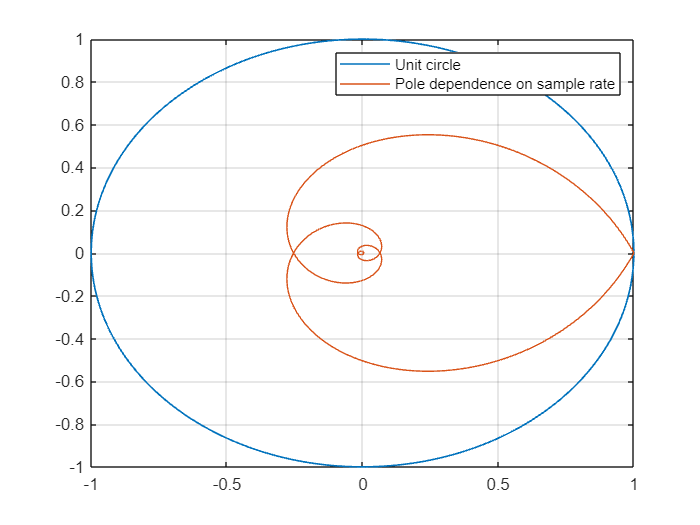

hold off

#### 4.1 Example

The pulse transfer function of a system is

$G\left(z\right)=\frac{z^2 -0\ldotp 3z-0\ldotp 1}{z^3 +3z^2 +2\ldotp 5z+1}$;  The sampling time is $T_s =1\ldotp$

Based on the pole-zero map analyse the stability of the system. As one pole is outside the unit circle at -2, the system is unstable.

% Analyse the stability of a discrete system based on its pole-zero map
disp('EXAMPLE 4.1')

EXAMPLE 4.1


disp('Analyse the stability of a discrete system based on pole-zero map')

Analyse the stability of a discrete system based on pole-zero map


Ts=1;
z=tf('z',Ts);
G=(z*z-0.3*z-0.1)/(z*z*z+3*z*z+2.5*z+1)

G =
 
     z^2 - 0.3 z - 0.1
  -----------------------
  z^3 + 3 z^2 + 2.5 z + 1
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


[zeros,poles,kd]=zpkdata(G,'v')

zeros =     0.5000
   -0.2000


poles =   -2.0000 + 0.0000i
  -0.5000 + 0.5000i
  -0.5000 - 0.5000i


kd = 1

abs(poles)

ans =     2.0000
    0.7071
    0.7071


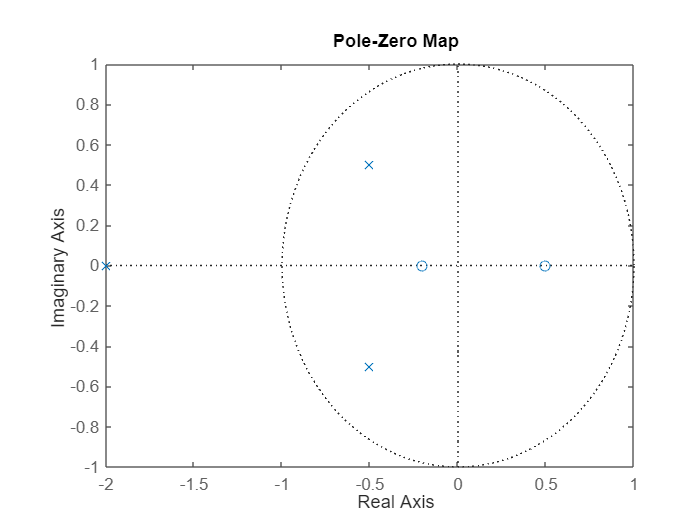

pzmap(G)

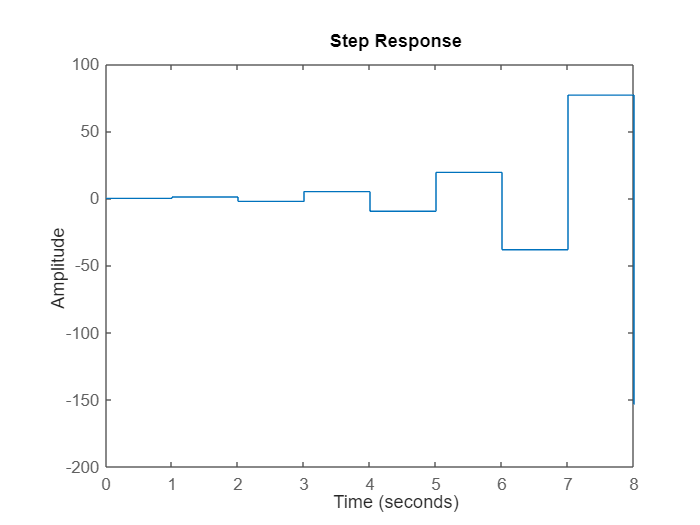

As one pole is outside the unit circle, the system is unstable.


step(G,8)

#### 4.2 Example

The continuous system is given by transfer function

$P\left(s\right)=\frac{1}{\left(1+10s\right)\left(1+5s\right)}$; The sampling time is $T_s =2\ldotp 5$. At the input zero order hold is applied.

In the feedback system the discrete controller is given by pulse transfer function


$$M\left(z\right)=10\;\frac{z-0\ldotp 7788}{z-1}\;\frac{z-0\ldotp 6065}{z}$$


Is the control system stable? Determine stability based on the pole-zero map of the closed loop system.

% Stability analysis of a closed loop control system
disp('EXAMPLE 4.2')

EXAMPLE 4.2


disp('The transfer function of the process')

The transfer function of the process


s=zpk('s');
Ts=2.5;
z=zpk('z',Ts);
P=1/((1+10*s)*(1+5*s))

P =
 
       0.02
  ---------------
  (s+0.1) (s+0.2)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The pulse transfer function')

The pulse transfer function


G=c2d(P,Ts,'zoh')

G =
 
   0.048929 (z+0.7788)
  ---------------------
  (z-0.7788) (z-0.6065)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The controller:')

The controller:


M=10*((z-0.7788)*(z-0.6065))/((z-1)*z)

M =
 
  10 (z-0.7788) (z-0.6065)
  ------------------------
          z (z-1)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The open loop:')

The open loop:


L=minreal(M*G,0.001)

L =
 
  0.48929 (z+0.7788)
  ------------------
       z (z-1)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The closed loop:')

The closed loop:


T=minreal(L/(1+L),0.001)

T =
 
     0.48929 (z+0.7788)
  ------------------------
  (z^2 - 0.5107z + 0.3811)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The pole-zero map:')

The pole-zero map:


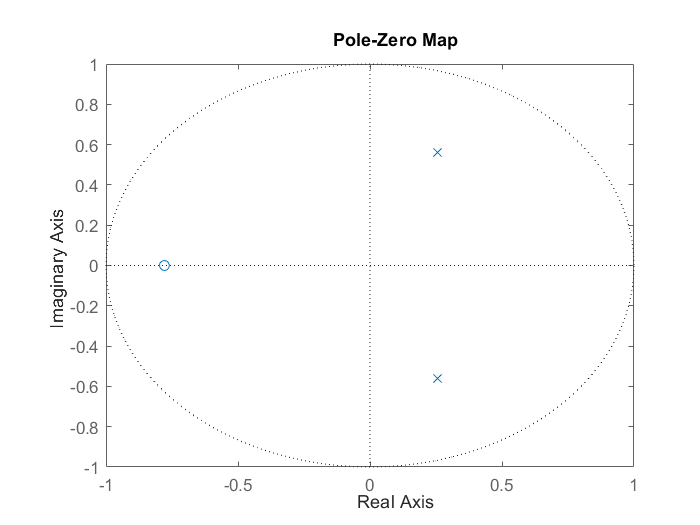

pzmap(T)

disp('The step response:')

The step response:


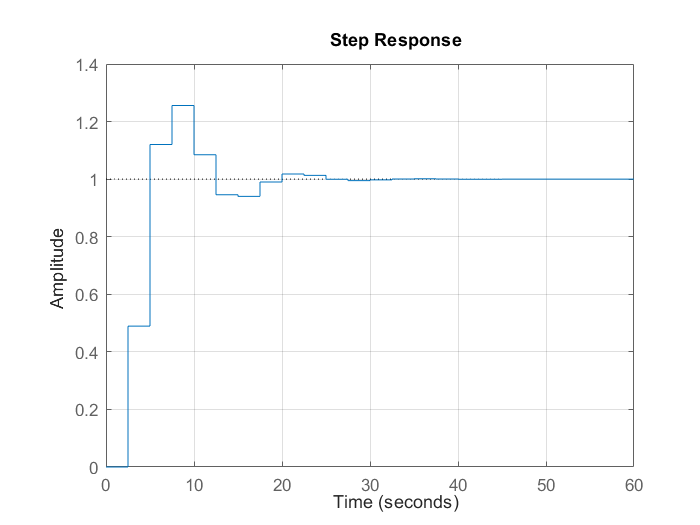

step(T),grid

Here the poles are all inside the unit circle so the system is stable and the closed-loop step response is convergent. It is noted that the values of the output signal are given only in the sampling points. Intersampling behaviour of the output signal would require use of the underlying continuous time model and tools such as SIMULINK. 

## 5. Root locus method 

Root-locus is a grapho-analytical method to show the poles of the closed-loop system while one parameter (typically the loop gain) in the system is changing from zero to infinity. Note that zero loop gain means open-loop system. 

[Modelling, Dynamics and Control - Chapter four: Classical control design techniques ](https://sites.google.com/sheffield.ac.uk/controleducation/chapterclassical) 

discusses the concept of root locus and shows also some simple rules for forming a sketch.

If the poles of the discrete closed loop system (the roots of the characteristic equation) are located inside the unit circle in the complex plane, the closed-loop system is stable. Poles outside of the unit circle mean unstable behaviour. The root locus is not just able to judge closed-loop stability, but also exhibits information on the dynamics of the closed loop system. If the poles are inside a given "heart curve" corresponding to a known damping ratio, then the transients are damped accordingly. The root locus shows how the change of the considered parameter influences stability and dynamics of the closed loop control system. 

MATLAB offers the **rlocus** command to draw the root locus. MATLAB command **rlocfind** is applied to find the gain belonging to a given point of the root locus. rlocfind puts up a crosshair cursor in the graphics window which is used to select a pole location on an existing root locus.

Analyse the stability of the closed loop system and determine the critical gain based on the root locus curves.

#### 5.1 Example

Consider  the control system given in example 4.2. The gain of the controller is changing from 1 to higher values. Determine the critical gain based on the root locus.

% Stability analysis of a closed loop control system based on the root
% locus method
disp('EXAMPLE 5.1')

EXAMPLE 5.1


disp('The transfer function of the process')

The transfer function of the process


s=zpk('s');
Ts=2.5;
z=zpk('z',Ts);
P=1/((1+10*s)*(1+5*s))

P =
 
       0.02
  ---------------
  (s+0.1) (s+0.2)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The pulse transfer function')

The pulse transfer function


G=c2d(P,Ts,'zoh')

G =
 
   0.048929 (z+0.7788)
  ---------------------
  (z-0.7788) (z-0.6065)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The controller:')

The controller:


M=((z-0.7788)*(z-0.6065))/((z-1)*z)

M =
 
  (z-0.7788) (z-0.6065)
  ---------------------
         z (z-1)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The open loop:')

The open loop:


L=minreal(M*G,0.001)

L =
 
  0.048929 (z+0.7788)
  -------------------
        z (z-1)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


%Root locus curves
disp('The root-locus curve may appear in a window outside of this livescript')

The root-locus curve may appear in a window outside of this livescript


rlocus(L)
disp('Determine the critical gain, then locate the cross on the crosspoint of the root locus and the imaginary axis and click')

Determine the critical gain, then locate the cross on the crosspoint of the root locus and the imaginary axis and click


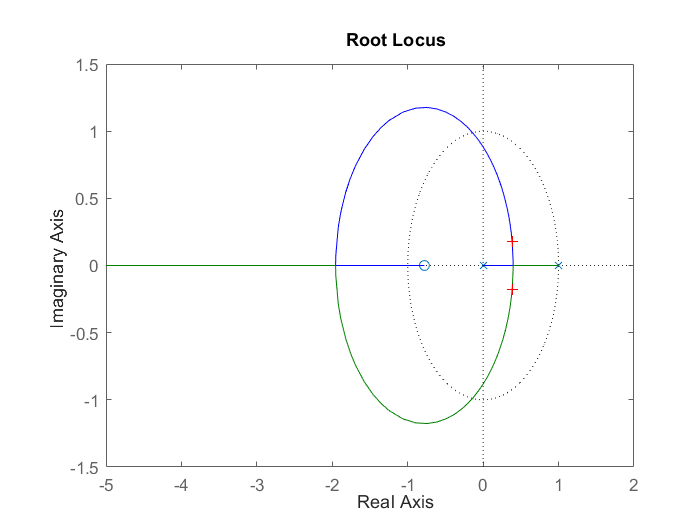

Select a point in the graphics window


selected_point = 0.4157 - 0.1861i

Kcrit = 4.7217

Kcrit = rlocfind(L)

disp('Check the step response of the system at the critical gain')

Check the step response of the system at the critical gain


t=0:Ts:100;
T1=minreal(Kcrit*L/(1+Kcrit*L),0.001)

T1 =
 
    0.23103 (z+0.7788)
  -----------------------
  (z^2 - 0.769z + 0.1799)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


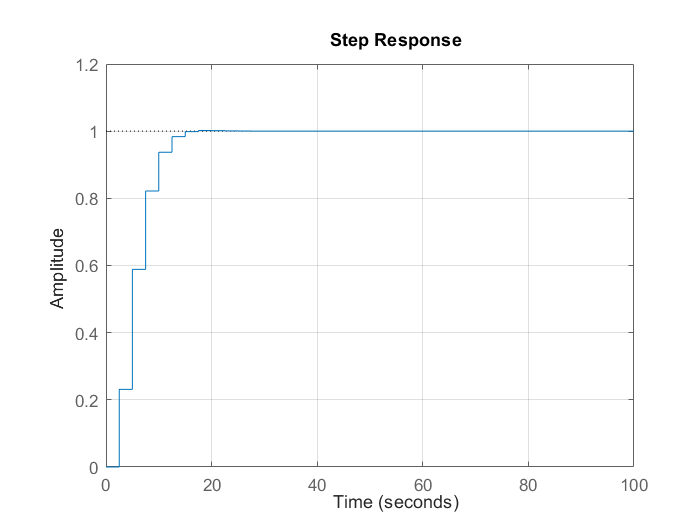

step(T1,t),grid

## 6. Stability analysis based on the Bode diagram

The stability of a closed loop control system can be analysed on the basis of the frequency function of the open loop.  

[Modelling, Dynamics and Control - Chapter four: Classical control design techniques ](https://sites.google.com/sheffield.ac.uk/controleducation/chapterclassical) 

The frequency function of a discrete system is obtained from its pulse transfer function by substituting 

$z=e^{i\omega T_s }$.

Let us remark that while $\omega \le \frac{1}{T_s }$ the amplitude-frequency diagrams of the continuous and the discrete systems are very close to each other. However, in the phase-frequency diagrams the effect of the zero order hold is seen more clearly, the discrete phase angle differs from the continuous phase angle approximately by $-\omega \frac{T_s }{2}\;\frac{180}{\pi }$ degrees, as it was seen that the zero order hold introduces an extra delay.

The examples below focus on stable systems, although of course with feedback the closed loop system may become unstable. As it was seen in case of continuous control systems stability can be analysed considering practical stability measures as e.g. phase margin and gain margin. These measures can be used also in case of discrete systems. Several measures exist to characterize how far a stable system is from being unstable.  

**Phase margin** defines the value of the phase angle of the open loop frequency function at the cut-off frequency. Phase margin can be expressed analytically as 

$\varphi_m =\varphi \left(\omega_c \right)+{180}^{\circ }$, where $\omega_c$ is the cut-off frequency where the absolute value of the open loop frequency function is 1.  The phase margin is illustrated on the figure below.   

The closed-loop system is stable if the phase margin is positive. For design purposes $60\degree$ phase margin is a typical prescription. In this case it is expected that the overshoot of the step response of the closed loop system is less than 10%.

**Gain margin** is the value the loop gain is to be multipled to push the closed-loop system to borderline stability.   $\textrm{gm}=\frac{1}{\left|L\left(j\omega_{\pi } \right)\right|}$   where $\omega_{\pi }$  is the frequency where the phase angle is ${-180}^{\circ }$. The gain margin can be read from the figure below. The closed loop system is stable if the gain margin exceeds 1.  A reasonable design prescription for the gain margin is around 2. 

The figure below shows the phase margin and the gain margin on the Bode diagram.

                   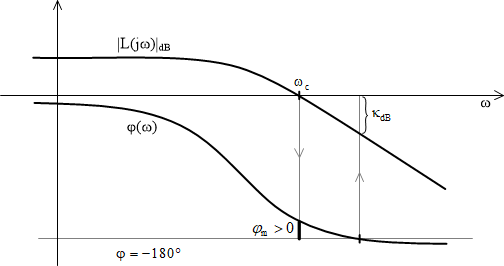

MATLAB offers the **margin** command to calculate and plot the phase and gain margin values. More examples in ***proportional_design_with_bode.mlx and   proportional_design_phase_margin.mlapp (virtual laboratory).***

#### Example 6.1

Determine the stability measures, the phase margin and the gain margin of the discrete control system analysed in example 4.2. It is seen that with the obtained phase margin the output signal is settled with about 30% overshoot and with the critical gain steady oscillations occur.

disp('EXAMPLE 6.1')

EXAMPLE 6.1


disp('The transfer function of the process')

The transfer function of the process


s=zpk('s');
Ts=2.5;
z=zpk('z',Ts);
P=1/((1+10*s)*(1+5*s))

P =
 
       0.02
  ---------------
  (s+0.1) (s+0.2)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The pulse transfer function')

The pulse transfer function


G=c2d(P,Ts,'zoh')

G =
 
   0.048929 (z+0.7788)
  ---------------------
  (z-0.7788) (z-0.6065)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The controller:')

The controller:


M=10*((z-0.7788)*(z-0.6065))/((z-1)*z)

M =
 
  10 (z-0.7788) (z-0.6065)
  ------------------------
          z (z-1)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The open loop:')

The open loop:


L=minreal(M*G,0.001)

L =
 
  0.48929 (z+0.7788)
  ------------------
       z (z-1)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The gain margin gm and the phase margin pm, frequency wg where ')

The gain margin gm and the phase margin pm, frequency wg where 


disp('the phase shift is -180 degrees and the cut-off frequency wc')

the phase shift is -180 degrees and the cut-off frequency wc


[gm,pm,wg,wc]=margin(L)

gm = 2.6245

pm = 46.0051

wg = 0.6853

wc = 0.3288

disp('Graphically on the Bode diagram')

Graphically on the Bode diagram


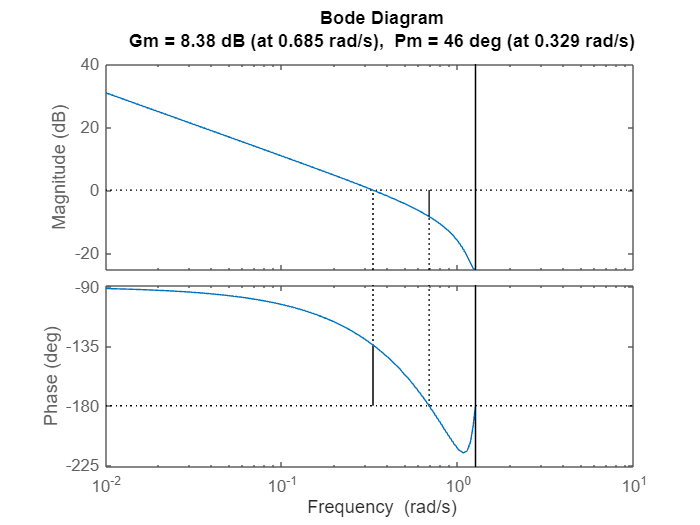

margin(L)

disp('The closed loop:')

The closed loop:


T=minreal(L/(1+L),0.001)

T =
 
     0.48929 (z+0.7788)
  ------------------------
  (z^2 - 0.5107z + 0.3811)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The step response:')

The step response:


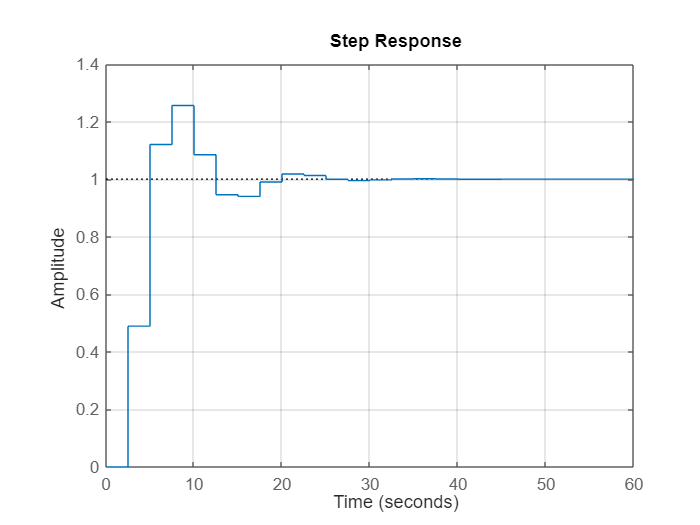

step(T),grid

Multiplying the compensator by the gm puts the closed loop system  on the boundary of stability as seen in the closed-loop step response here.

Tcrit=minreal(gm*L/(1+gm*L),0.001)

Tcrit =
 
   1.2841 (z+0.7788)
  -------------------
  (z^2 + 0.2841z + 1)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


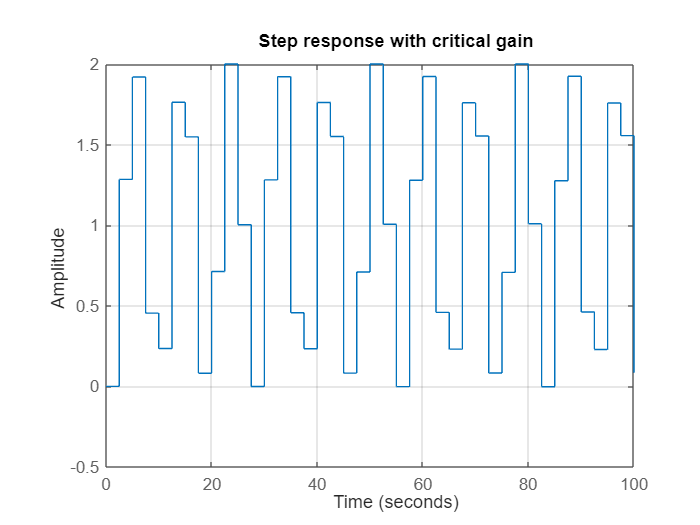

t=0:2.5:100;
step(Tcrit,t),grid
title('Step response with critical gain')